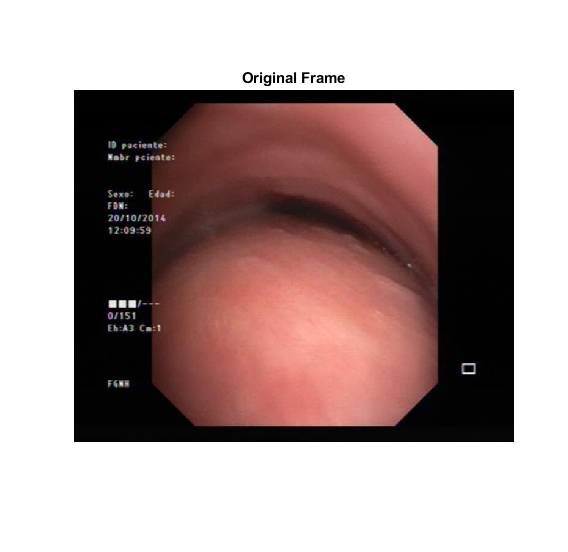

% cd frames\sick1\

% frame = imread('676.jpg');
% frame = imread('112.jpg');
frame = imread('676.jpg');
imshow(frame);
title('Original Frame');

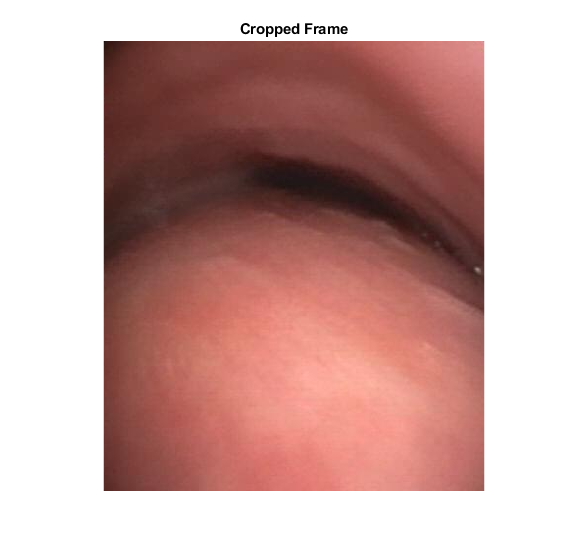


% //////// PREPROCESSING \\\\\\\\\\
% ------- Image Cropping ----------
frameCropped = imcrop(frame,[168,54,387,458]);
imshow(frameCropped);
title('Cropped Frame');

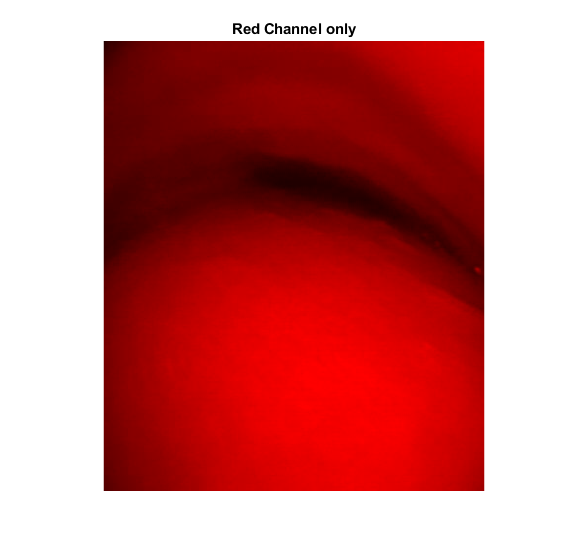

% ---------------------------------

% //////// BEST FEATURES \\\\\\\\\\
% ----------- Redness -------------
frameRChannel = frameCropped(:,:,1);
% Create an all black channel.
allBlack = zeros(size(frameCropped, 1), size(frameCropped, 2), 'uint8');
% Create a color version of the Red Channel
frameRed = cat(3, frameRChannel, allBlack, allBlack);
% Print red channel
imshow(frameRed);
title('Red Channel only');

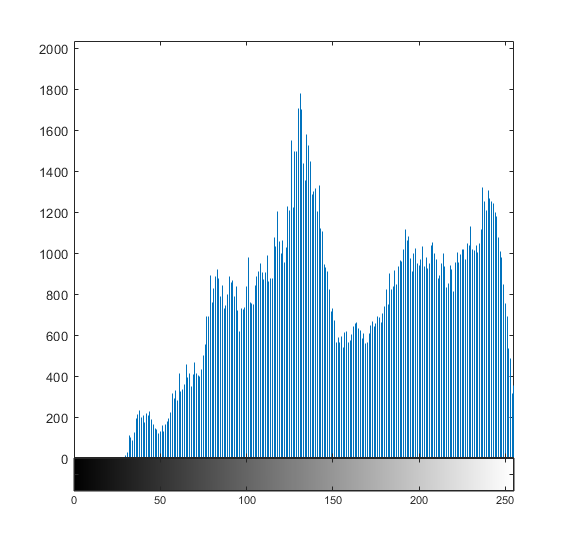

imhist(frameRChannel);

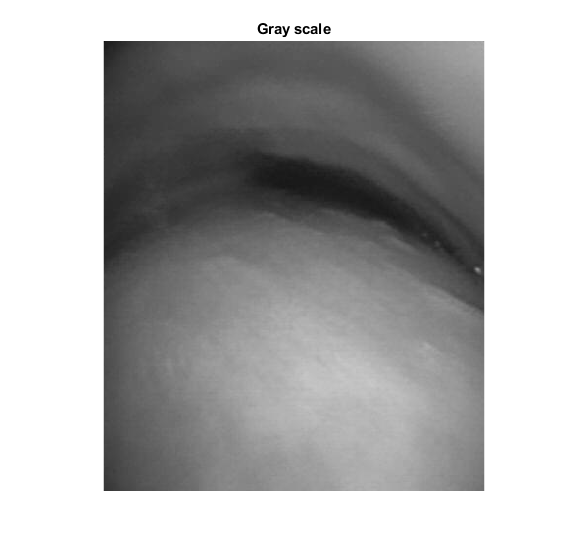


% ----------- Grayness ------------
frameGray = rgb2gray(frameCropped);
imshow(frameGray);
title('Gray scale');

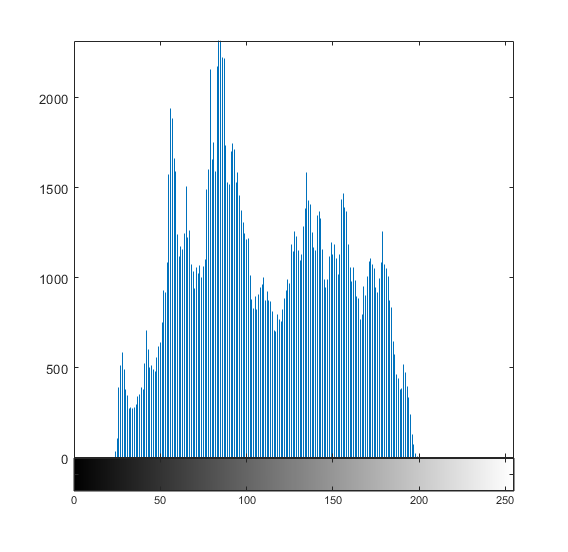

imhist(frameGray);

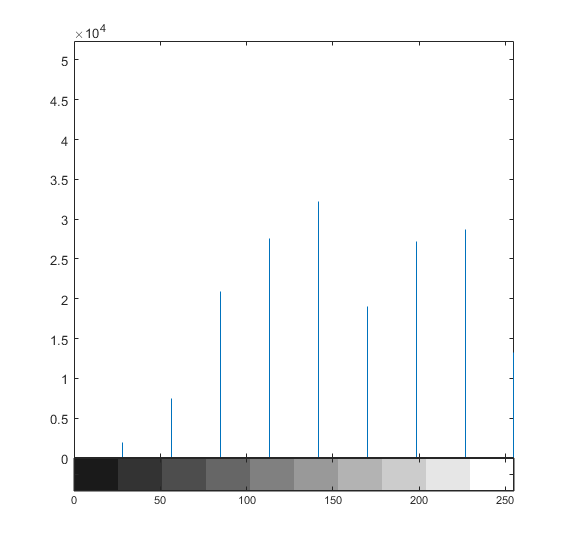

% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////
% \\\\\\\\\\\\\\\|/////////////////

% ///////// SEGMENTATION \\\\\\\\\\
% --------- Binarization ----------
% Image histogram with 6 bins
imhist(frameRChannel,10);

[counts,binLocations] = imhist(frameRChannel,6);
counts = counts(2:size(counts));
binLocations = binLocations(2:size(binLocations));
% Getting maximum difference between bins
[dist,ix] = max(diff(counts))

dist =        33698

ix =      1

% Setting the threshold to the difference
binThresh = ceil(abs((binLocations(ix + 1) + binLocations(ix))) / 2) 

binThresh =     77

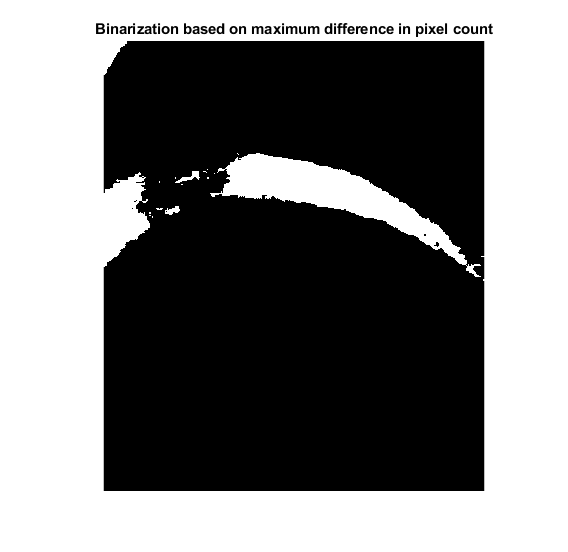


% Manual binaritzation
binFrameManual = frameRChannel < binThresh;

% Otsu binarization
level = graythresh(frameRChannel);
binFrameOtsu = imbinarize(frameRChannel,level);

% Adaptive binarization
binFrameAdaptive = imbinarize(frameRChannel,"adaptive", ...
    "ForegroundPolarity","bright","Sensitivity",0.66);

% Image Printing
imshow(binFrameManual);
title('Binarization based on maximum difference in pixel count');

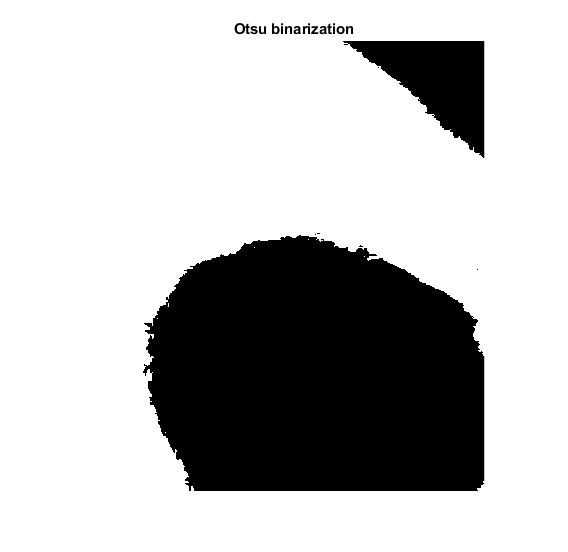

imshow(~binFrameOtsu);
title('Otsu binarization');

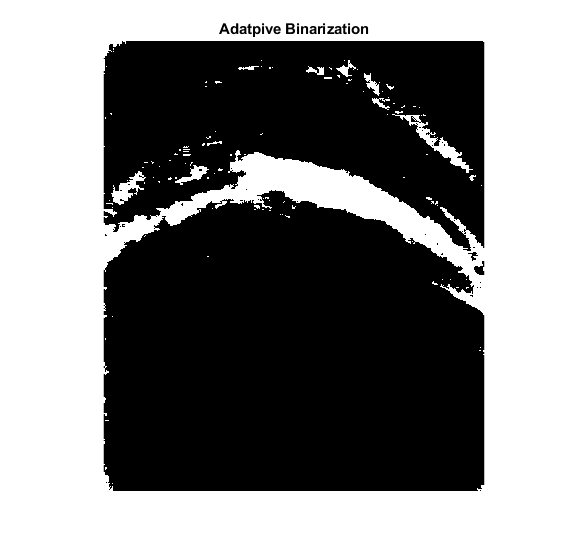

imshow(~binFrameAdaptive);
title('Adatpive Binarization');

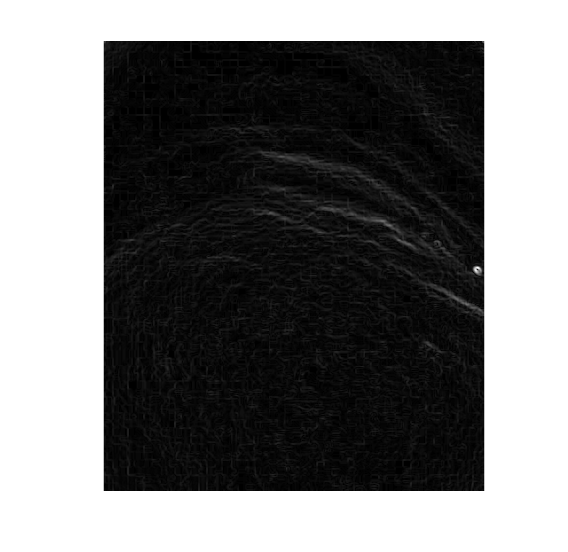

% ---------------------------------

% ---------- Watershed ------------
% ----------- Gradient  -----------
gmag = imgradient(frameRChannel);
imshow(gmag,[]);

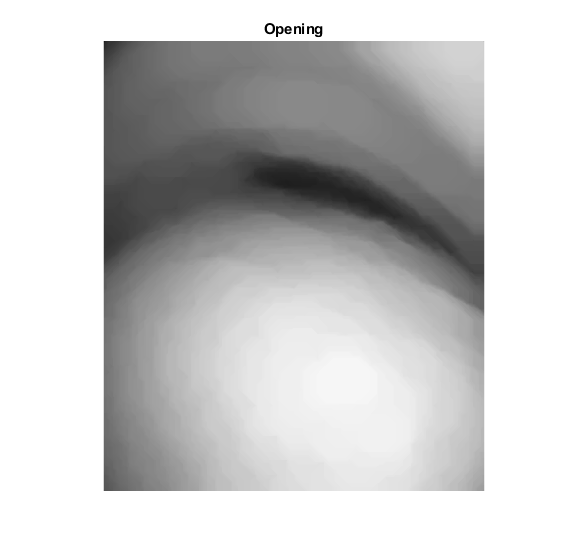


se = strel('disk',20);
Io = imopen(frameRChannel,se);
imshow(Io)
title('Opening')

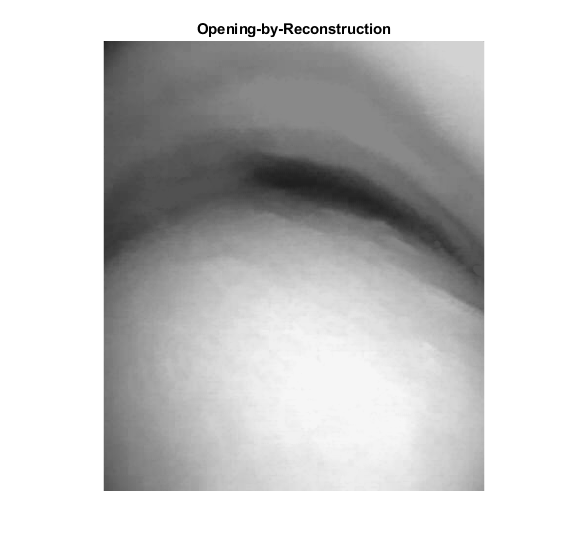


Ie = imerode(frameRChannel,se);
Iobr = imreconstruct(Ie,frameRChannel);
imshow(Iobr)
title('Opening-by-Reconstruction')

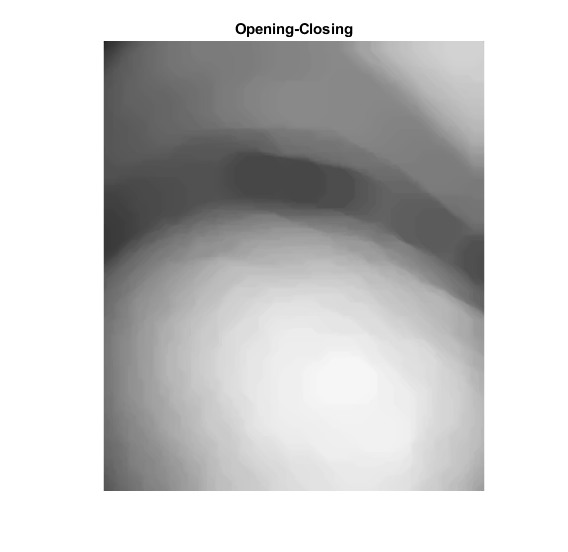


Ioc = imclose(Io,se);
imshow(Ioc)
title('Opening-Closing')

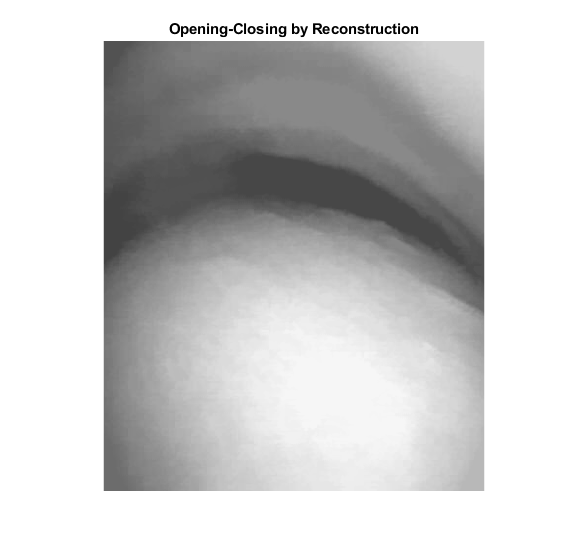


Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
imshow(Iobrcbr)
title('Opening-Closing by Reconstruction')

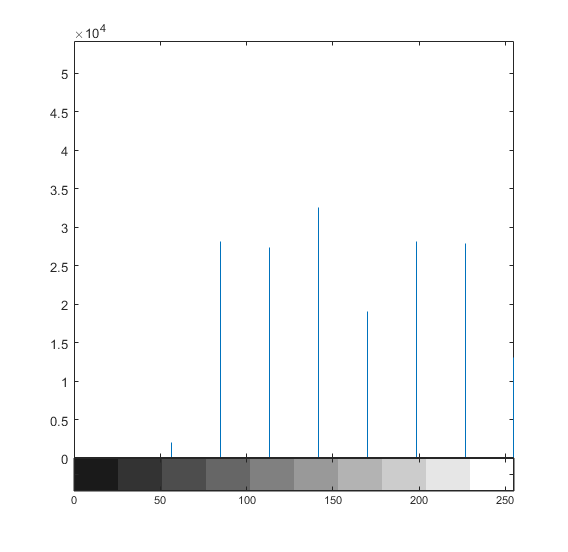


% --------- Binarization ----------
% Image histogram with 6 bins
imhist(Iobrcbr,10);

[counts,binLocations] = imhist(Iobrcbr,20);
counts = counts(2:size(counts));
binLocations = binLocations(2:size(binLocations));
% Getting maximum difference between bins
[dist,ix] = max(diff(counts))

dist =        10156

ix =      4

% Setting the threshold to the difference
binThresh = ceil(abs((binLocations(ix + 1) + binLocations(ix))) / 2)

binThresh =     61

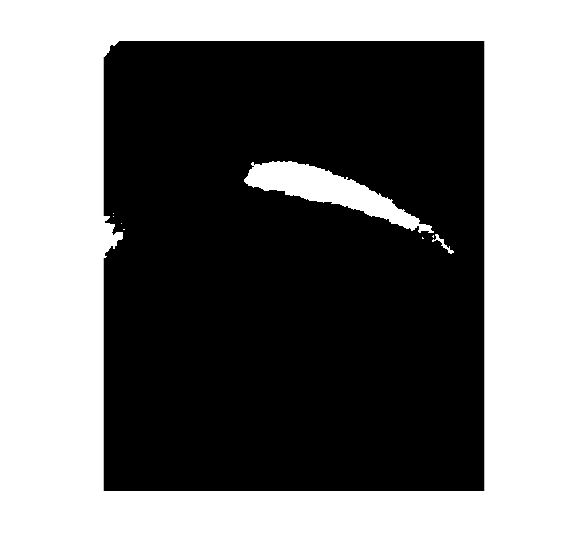

% Manual binaritzation
binFrameManual = frameRChannel < binThresh;
imshow(binFrameManual)

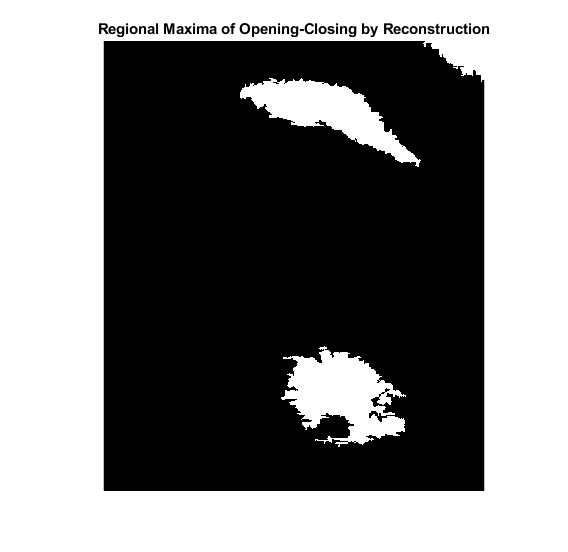

% ---------------------------------

maximums = imregionalmax(Iobrcbr);
imshow(maximums)
title('Regional Maxima of Opening-Closing by Reconstruction')

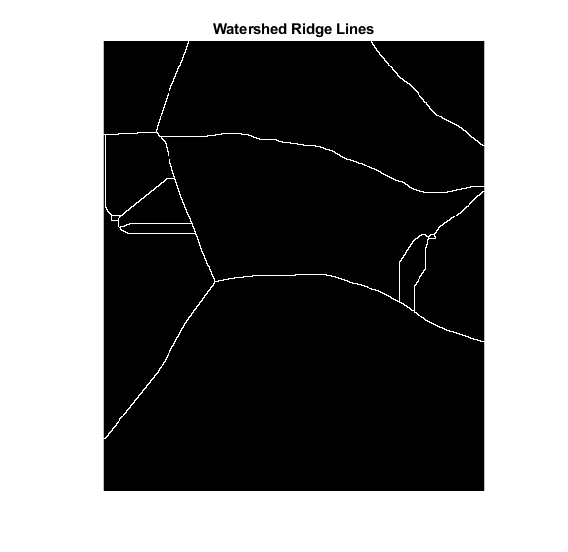


D = bwdist(maximums | binFrameManual);
DL = watershed(D);
bgm = DL == 0;
imshow(bgm)
title('Watershed Ridge Lines')

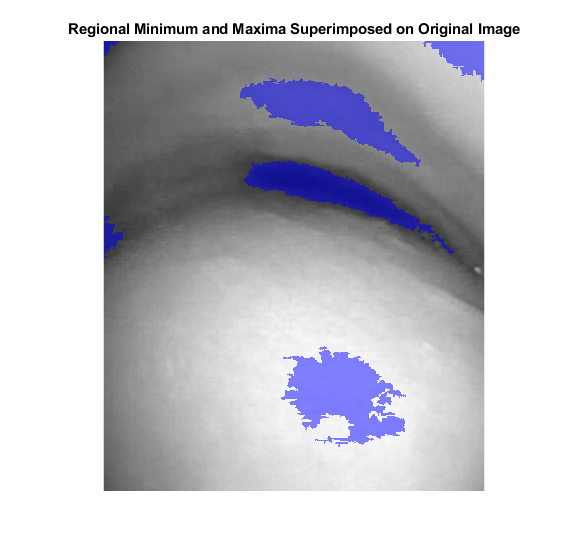


I2 = labeloverlay(frameRChannel,binFrameManual | maximums);
imshow(I2)
title('Regional Minimum and Maxima Superimposed on Original Image')

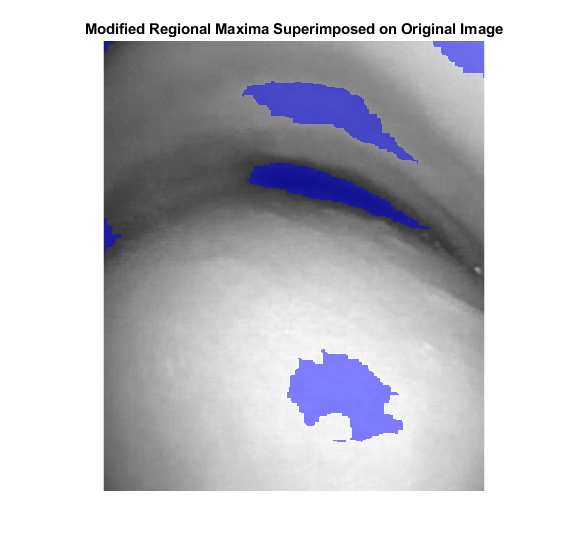


se2 = strel(ones(5,5));
fgm2 = imclose(binFrameManual | maximums,se2);
fgm3 = imerode(fgm2,se2);
fgm4 = bwareaopen(fgm3,20);
I3 = labeloverlay(frameRChannel,fgm4);
imshow(I3)
title('Modified Regional Maxima Superimposed on Original Image')

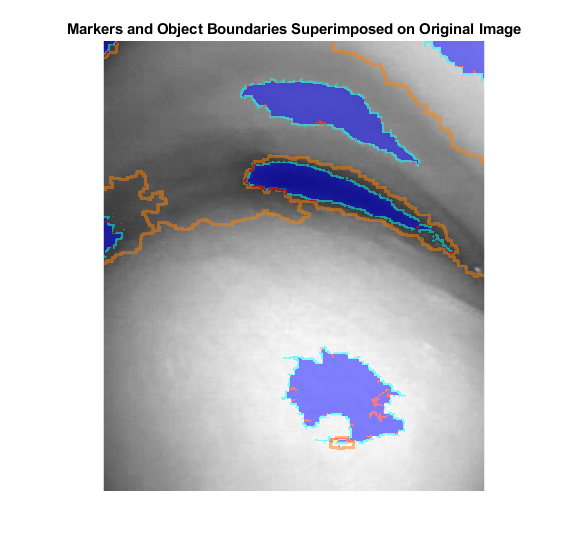


gmag2 = imimposemin(gmag, fgm4);
L = watershed(gmag2);
labels = imdilate(L==0,ones(3,3)) + 2*(binFrameManual | maximums) + 3*fgm4;
I4 = labeloverlay(frameRChannel,labels);
imshow(I4)
title('Markers and Object Boundaries Superimposed on Original Image')

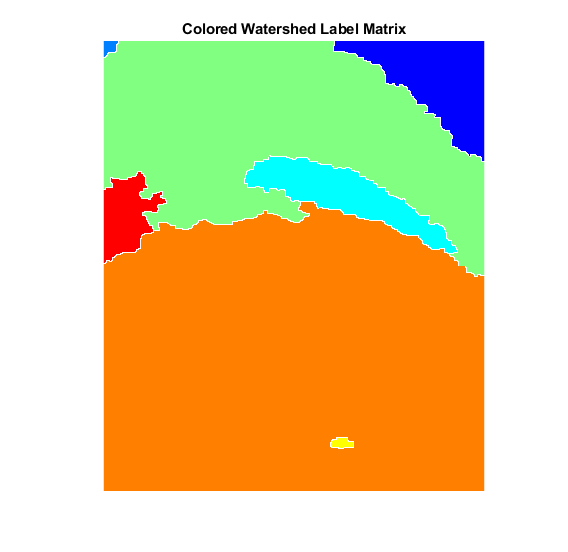


Lrgb = label2rgb(L,'jet','w','shuffle');
imshow(Lrgb)
title('Colored Watershed Label Matrix')

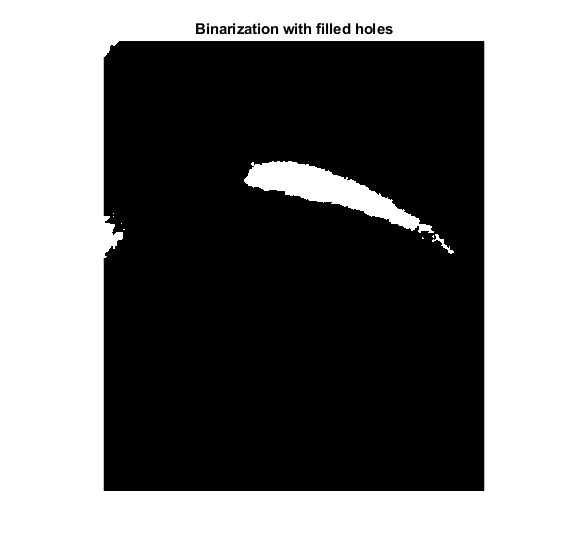

% ---------------------------------
% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////

% //////// POSTPROCESSING \\\\\\\\\\
% -------- Filling holes ----------
filledFrame = imfill(binFrameManual,8,'holes');
imshow(filledFrame);
title('Binarization with filled holes');

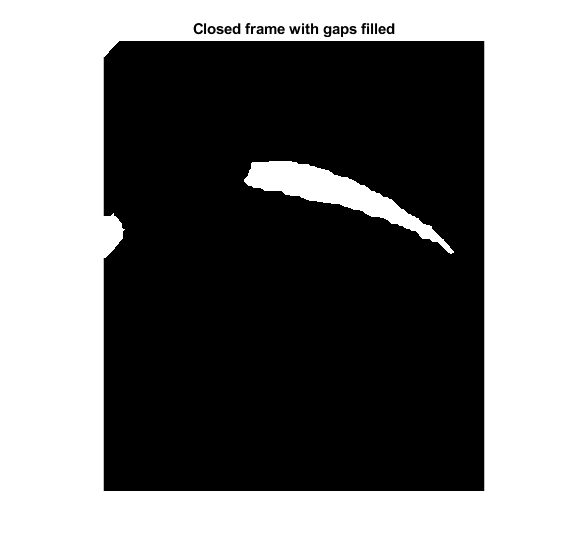

% ---------------------------------

% ---------- Closing gaps ---------
% With disks
% SE = strel('disk',15,8);
% closedFrame = imclose(filledFrame,SE);
% imshow(closedFrame); % Circle closed
% closedFilledFrame = imfill(closedFrame,8,'holes');
% imshow(closedFilledFrame);

% With lines
positiveSlope = strel('line',15,45);
negativeSlope = strel('line',15,-45);
horizontal = strel('line',15,0);
vertical = strel('line',15,90);
closedFrame=imclose(filledFrame,positiveSlope);
closedFrame=imclose(closedFrame,negativeSlope);
closedFrame=imclose(closedFrame,horizontal);
closedFrame=imclose(closedFrame,vertical);
closedFilledFrame = imfill(closedFrame,8,'holes');
imshow(closedFilledFrame);
title('Closed frame with gaps filled');

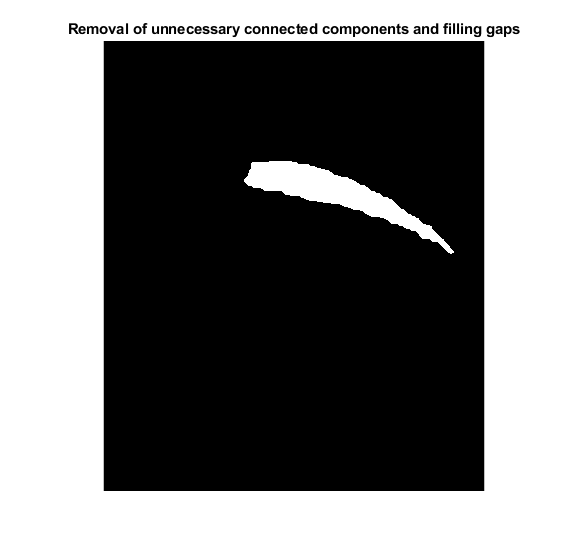

% ---------------------------------

% -- Removing small Conn. Comp. ---
props = regionprops(closedFilledFrame, 'Area');
allAreas = [props.Area];
cleanedFrame = bwareaopen(closedFilledFrame, ceil(max(allAreas)/2));
imshow(cleanedFrame);
title('Removal of unnecessary connected components and filling gaps');

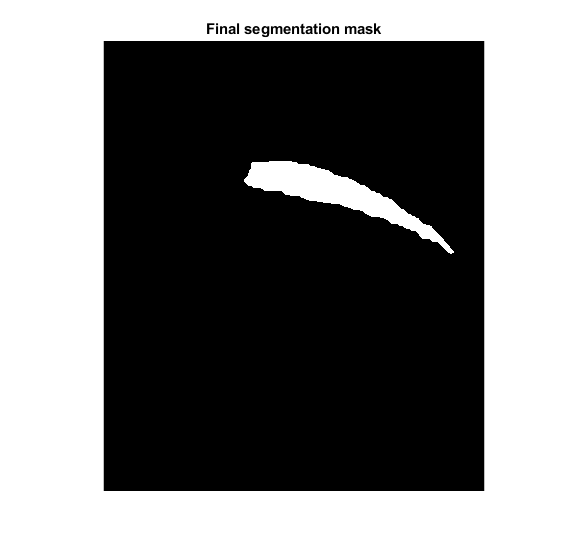

% ---- Extracting largest Blobs ---
% blobFrame = ExtractNLargestBlobs(cleanedFrame, 1);
% imshow(blobFrame);
positiveSlope = strel('line',25,45);
negativeSlope = strel('line',25,-45);
horizontal = strel('line',25,0);
vertical = strel('line',25,90);
closeBlobFrame=imclose(cleanedFrame,positiveSlope);
closeBlobFrame=imclose(closeBlobFrame,negativeSlope);
closeBlobFrame=imclose(closeBlobFrame,horizontal);
closeBlobFrame=imclose(closeBlobFrame,vertical);
closeBlobFrame = imfill(closeBlobFrame,8,'holes');
imshow(closeBlobFrame);
title('Final segmentation mask');

% ---------------------------------
% ---------------------------------

% ----- Threading the needle ------
% ---------- Convex hull ----------
% unionFrame = bwconvhull(blobFrame, 'Union');
% imshow(unionFrame);
% ---------------------------------
% -------- Active Countour --------
%numberOfIterations = 100;
%bw = activecontour(frameRChannel, unionFrame, numberOfIterations, 'edge');
%imshow(bw);
% ---------------------------------
% ---------------------------------
% \\\\\\\\\\\\\\\|/////////////////

% Getting the area
area = bwarea(closeBlobFrame)

area =                     5328.5

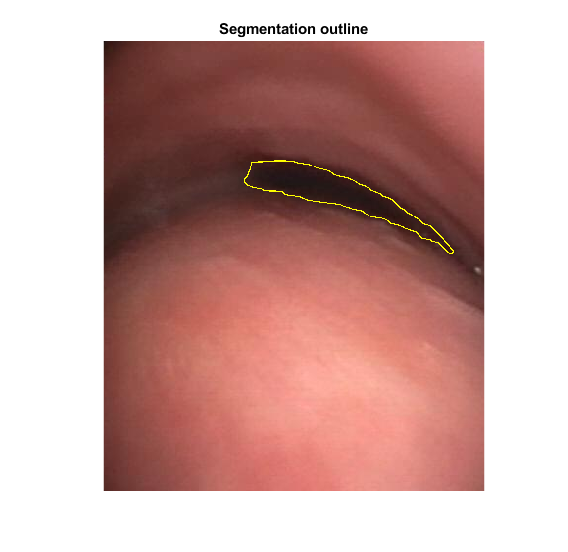

edgeDetected = edge(closeBlobFrame,"canny");
frameOutlined = imoverlay(frameCropped,edgeDetected,'yellow');
imshow(frameOutlined);
title('Segmentation outline');

% cd ..\..\

function binaryImage = ExtractNLargestBlobs(binaryImage, numberToExtract)
try
  % Get all the blob properties.  Can only pass in originalImage in version R2008a and later.
  [labeledImage, numberOfBlobs] = bwlabel(binaryImage);
  blobMeasurements = regionprops(labeledImage, 'area');
  % Get all the areas
  allAreas = [blobMeasurements.Area];
  if numberToExtract > 0
    % For positive numbers, sort in order of largest to smallest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'descend');
  elseif numberToExtract < 0
    % For negative numbers, sort in order of smallest to largest.
    % Sort them.
    [sortedAreas, sortIndexes] = sort(allAreas, 'ascend');
    % Need to negate numberToExtract so we can use it in sortIndexes later.
    numberToExtract = -numberToExtract;
  else
    % numberToExtract = 0.  Shouldn't happen.  Return no blobs.
    binaryImage = false(size(binaryImage));
    return;
  end
  % Extract the "numberToExtract" largest blob(a)s using ismember().
  biggestBlob = ismember(labeledImage, sortIndexes(1:numberToExtract));
  % Convert from integer labeled image into binary (logical) image.
  binaryImage = biggestBlob > 0;
catch ME
  errorMessage = sprintf('Error in function ExtractNLargestBlobs().\n\nError Message:\n%s', ME.message);
  fprintf(1, '%s\n', errorMessage);
  uiwait(warndlg(errorMessage));
end
end